## Lecture 15

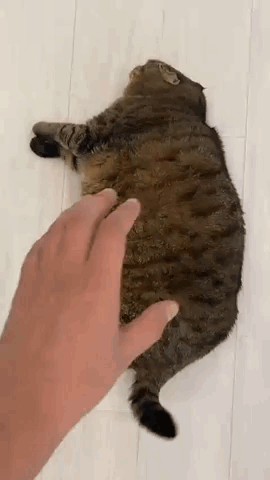

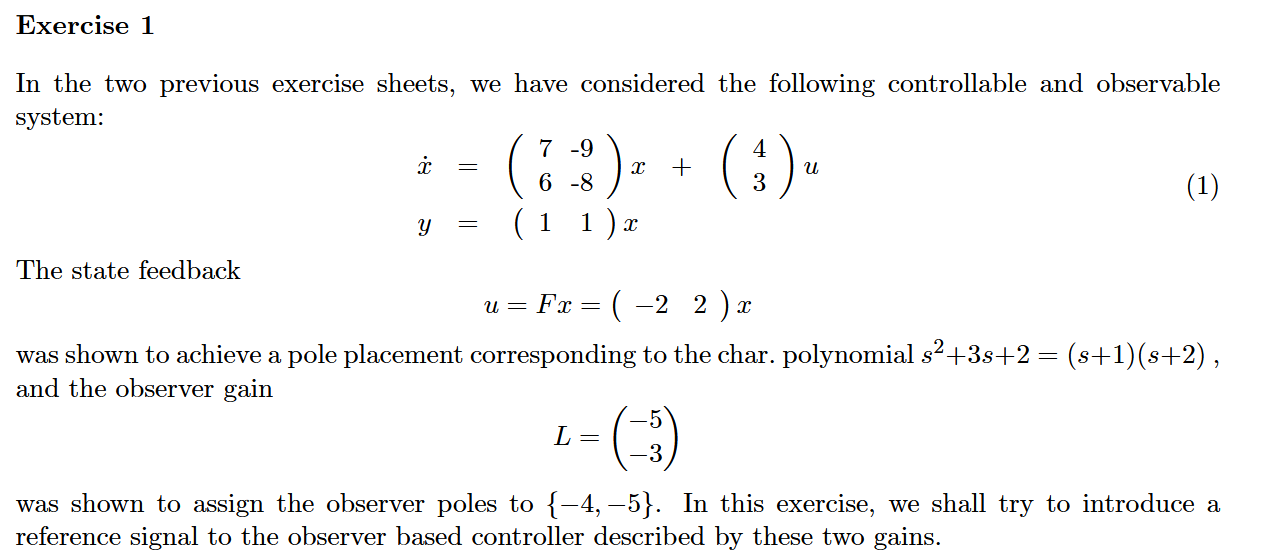

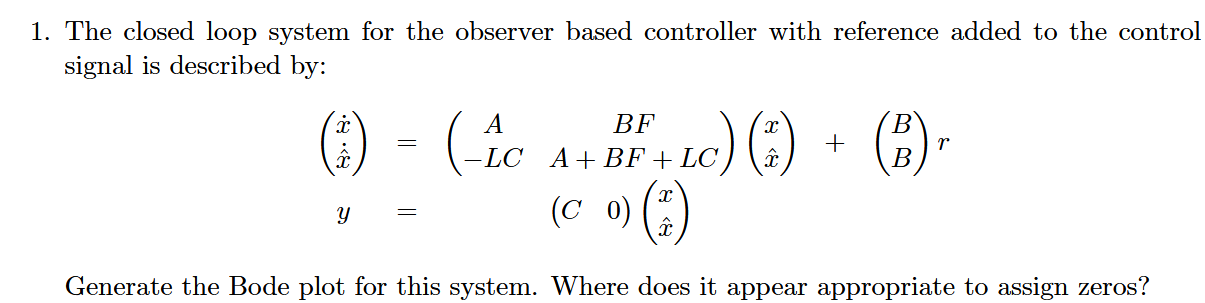

A = [7 -9; 6 -8];
B = [4;3];
C = [1 1];
F = [-2 2];
L = [-5; -3];

A1 = [2 -3; 4 -5];
B1 = [2;3];
C1 = [-3 2];
F1 = [22 -16];
L1 = [-122;-192];
sys = ss([A B*F; -L*C A+(B*F)+(L*C)],[B;B], [C 0 0; 0 0 0 0; 0 0 0 0; 0 0 0 0], 0);
% bodeplot(sys(1)/4);

#### Bodeplot:

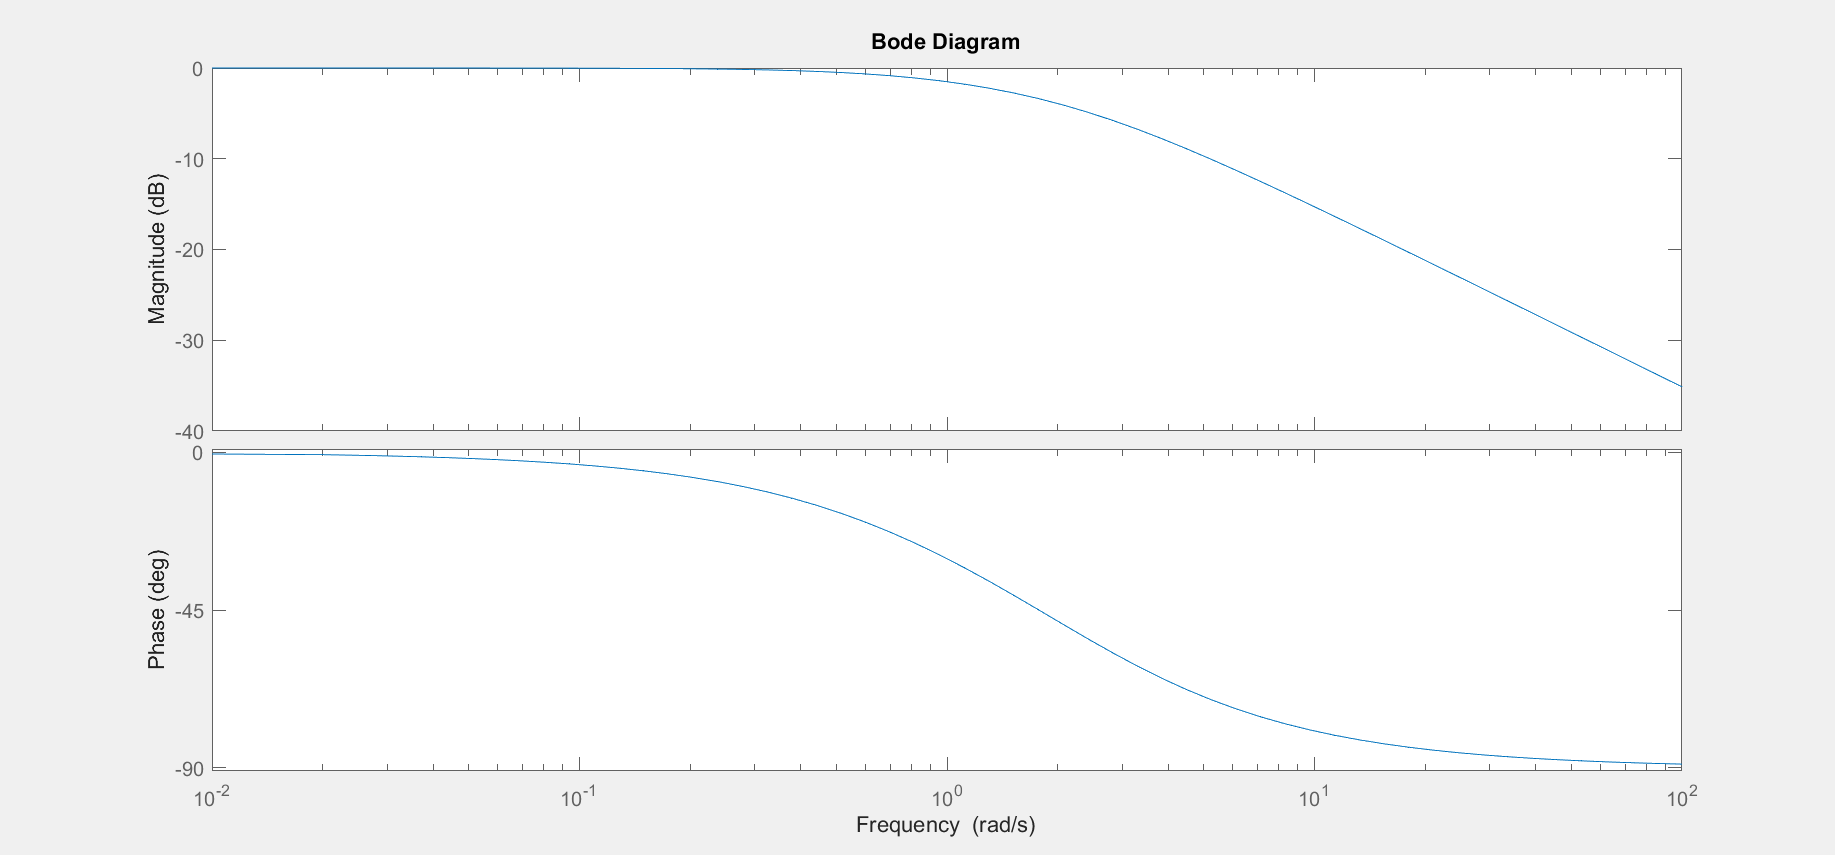

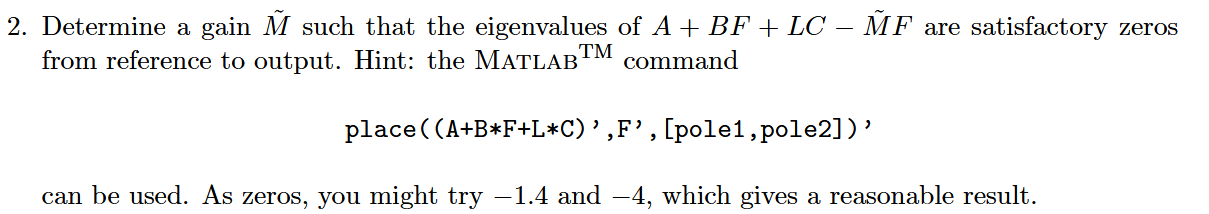

Mtilde = place((A+(B*F)+(L*C))',F',[-1.4 -4])'

Mtilde =                        7.6
                       4.8


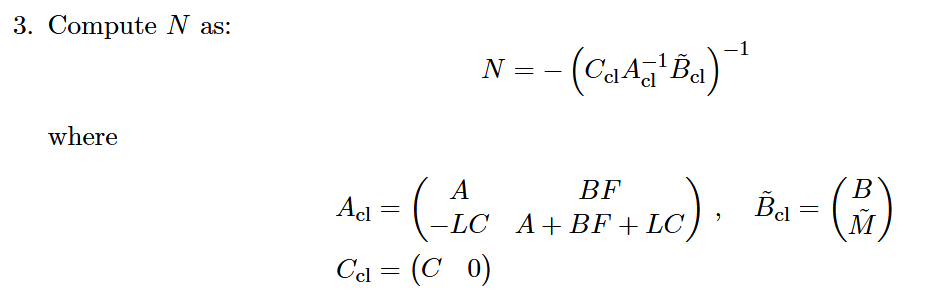

Acl = [A B*F; -L*C A+(B*F)+(L*C)];
Bcl = [B;Mtilde];
Ccl = [C 0 0];

N = -inv((Ccl*inv(Acl)*Bcl))

N =          0.892857142857139


M = Mtilde*N

M =           6.78571428571426
          4.28571428571427


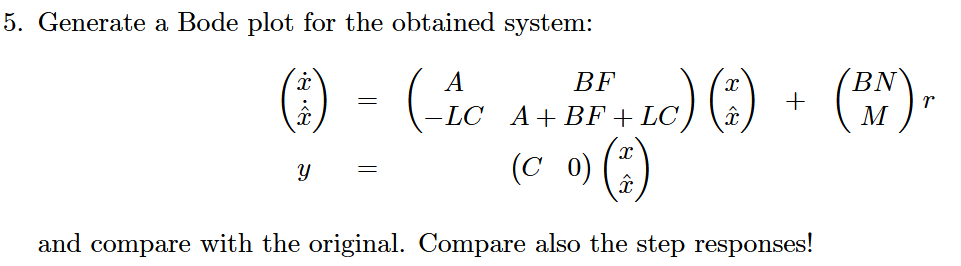

B1 = [B*N; M];
sys1 = ss([A B*F; -L*C A+(B*F)+(L*C)],B1, [C 0 0], 0)
% bodeplot(sys1(1))
% step(sys(1)/4);
% hold on
% step(sys1(1))
% legend

#### Bodeplot:

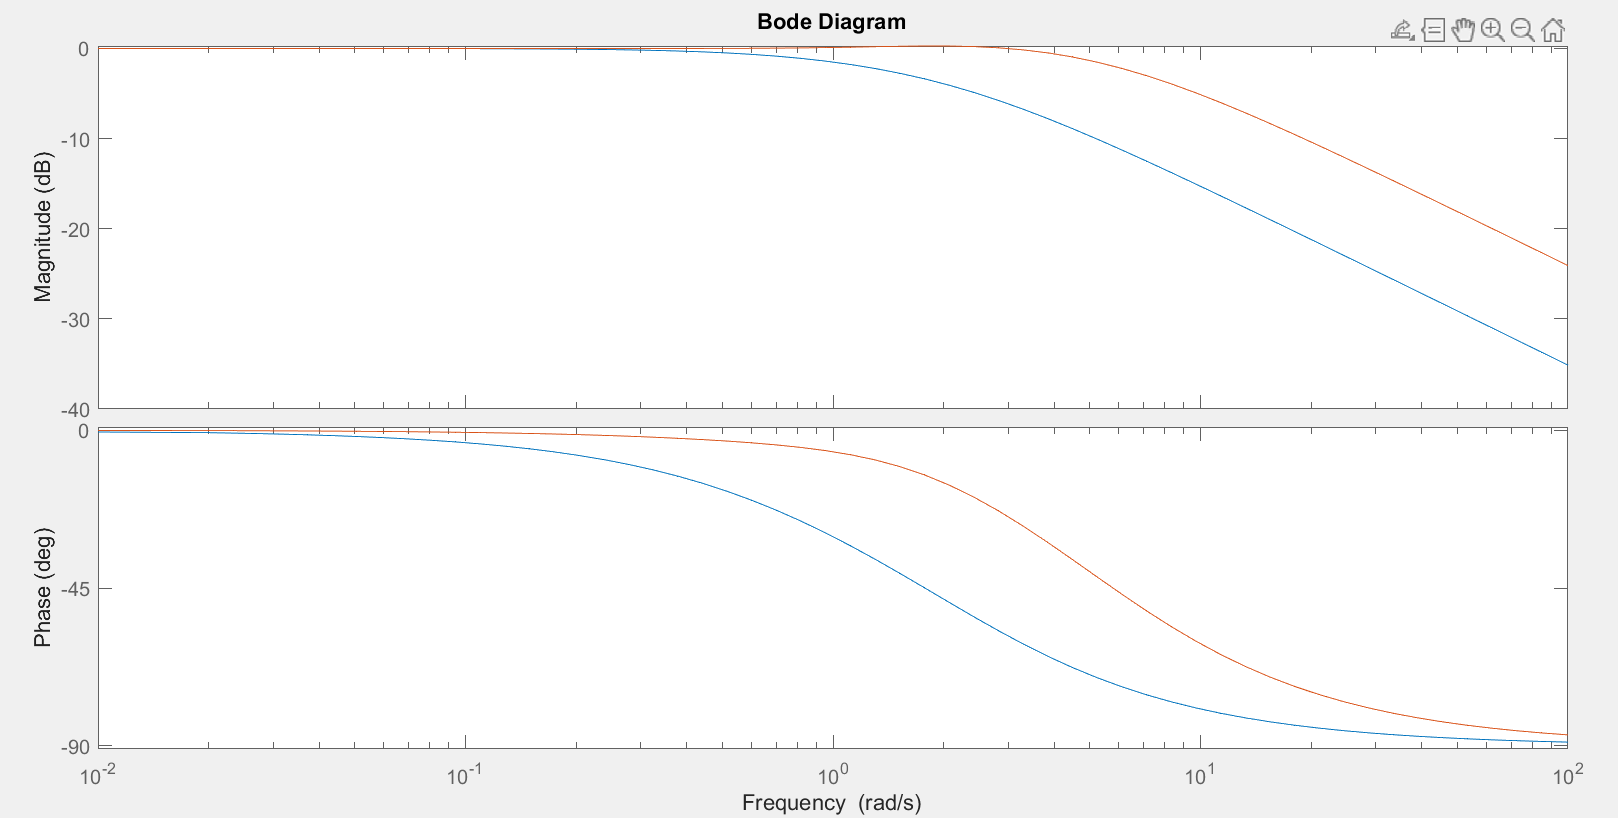

#### Step:

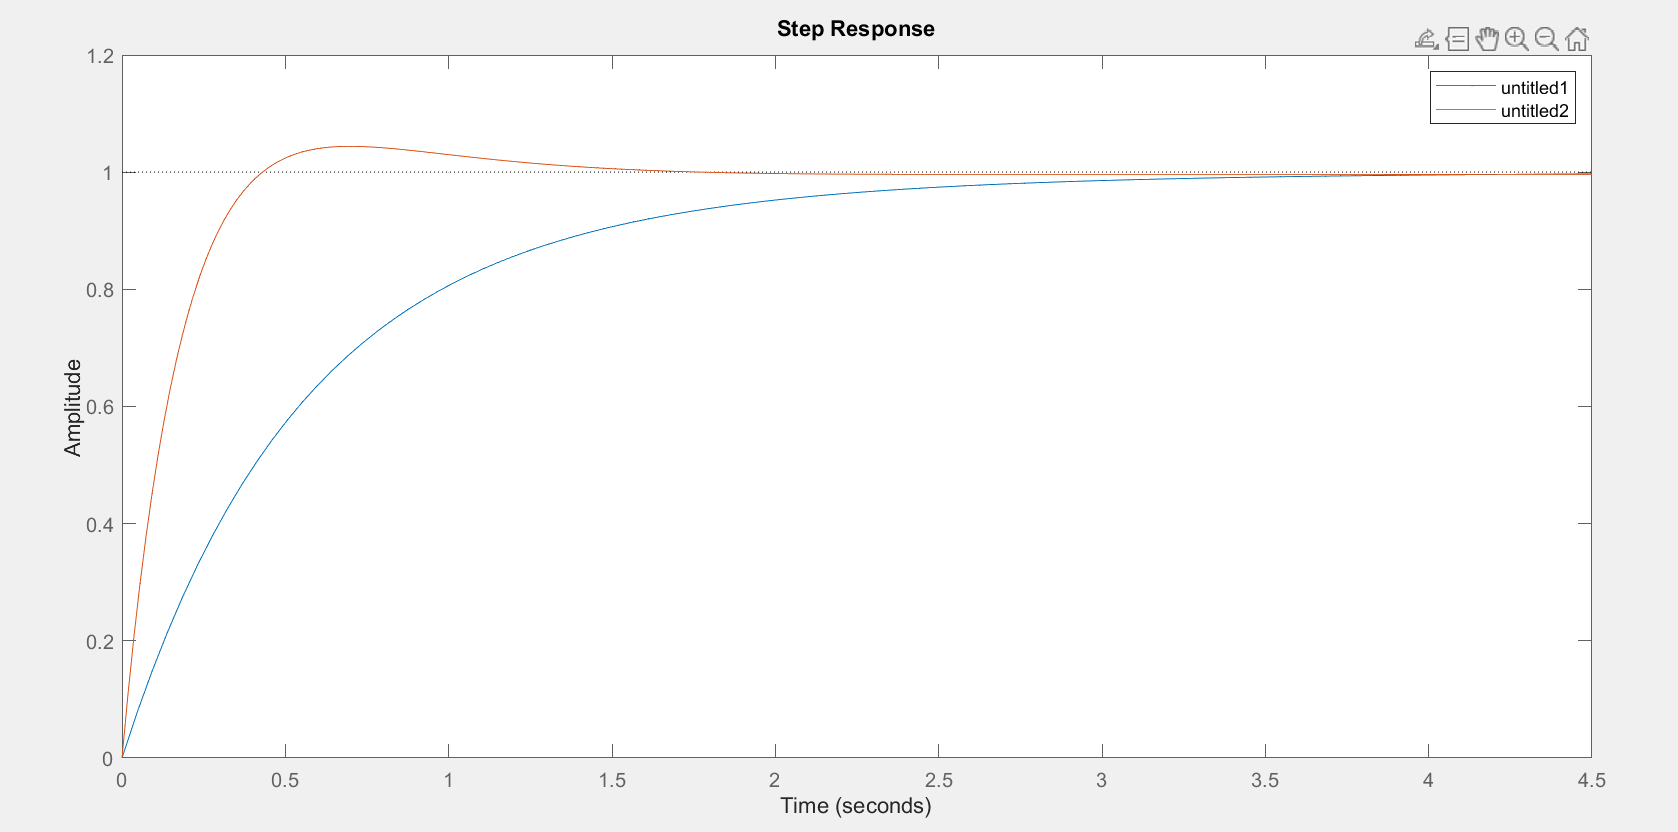

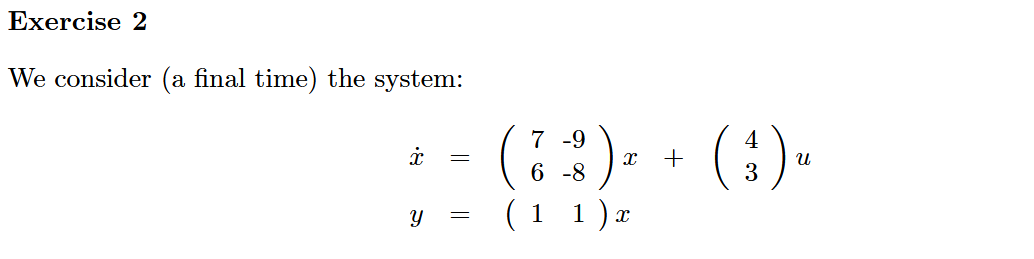

    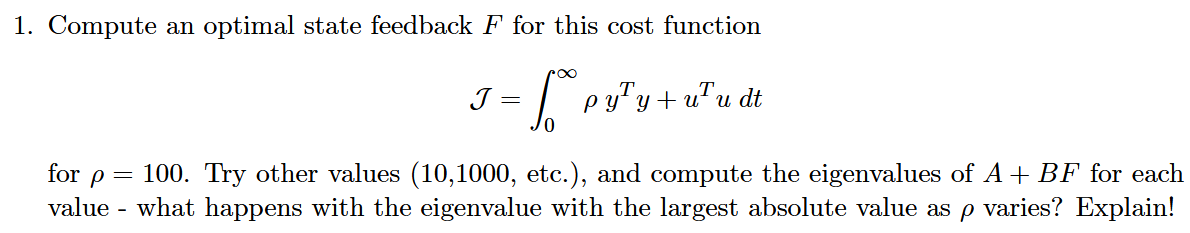

close all
clear
A = [7 -9; 6 -8];
B = [4;3];
C = [1 1];
F = [-2 2];
L = [-5; -3];
Fopt = -lqr(A,B,1000*C'*C,1);
eig(A + B*Fopt) %Større rho giver poler der rykke mod venstre deraf giver større styresignal for et hurtigere system og modsat.

ans =          -221.367779711457
         -1.14284978018868


sys1 = ss(A,B,C,0);
zero(sys1)

ans =          -1.14285714285714


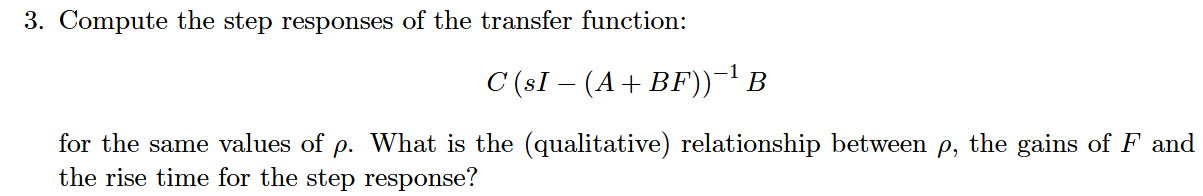

s = tf('s');
sys2 = C*inv(s*eye(2) - (A + (B*Fopt)))*B;
step(sys2);

#### Step response: